% Open file to be transmitted and create bytestream

fid = fopen('symbols.txt');
x=fread(fid,'*char');
byteArr = dec2bin(x,8);
byteArrTransposed=transpose(byteArr);
binaryStream=byteArrTransposed(:)-'0';
numRSPackets=ceil(length(byteArr)/223);
data=zeros(223*8*numRSPackets,1);
data(1:length(binaryStream))=binaryStream;
%data=zeros(223*8,1)
%data(1:223*8)=binaryStream(1:223*8)
%create encoder
n=255;
k=223;
rsencoder = comm.RSEncoder(n,k,'BitInput',true);
rsdecoder = comm.RSDecoder(n,k,'ErasuresInputPort',true,'NumCorrectedErrorsOutputPort',true,'BitInput',true);
%encode data and generate images

encData=rsencoder(data)';
symbolStream=zeros(length(encData)/3,1);
j=1;
for i=1:3:length(encData)
    symbol = bi2de(encData(i:i+2),'left-msb');
    symbolStream(j)=symbol;
    j=j+1;
end

label=randi([0 7],1,400)


label1=[2 5 0 6 4 1 4 5 1 0 0 5 0 1 6 2 3 3 6 6 5 1 4 5 3 0 6 7 2 0 4 0 2 1 6 7 2 5 6 4 3 1 2 6 7 1 4 2 3 1 2 7 1 1 4 7 1 0 0 4 2 5 0 2 3 3 6 6 7 5 5 3 1 0 0 6 7 5 4 6 1 0 0 5 2 1 5 0 3 1 2 2 0 1 0 1 3 1 0 7 3 1 4 5 3 3 4 7 2 1 6 5 3 4 4 6 2 5 6 3 1 0 0 6 7 5 4 6 1 0 0 5 1 5 5 0 3 1 2 7 1 1 5 4 3 3 6 6 1 5 5 3 1 0 0 4 4 1 5 7 3 3 0 6 6 5 4 5 3 4 6 0 5 1 4 2 3 6 2 2 0 1 2 3 3 2 2 7 1 0 4 0 2 0 2 7 1 1 6 4 3 2 0 7 2 5 6 2 1 0 0 4 1 5 5 7 3 3 4 6 0 5 5 6 1 0 0 4 2 1 5 7 3 6 2 6 6 1 4 5 0 2 4 2 4 0 4 3 1 4 2 3 2 4 4 0 3 2 2 6 7 0 4 0 3 3 6 7 2 5 6 2 1 0 0 7 1 5 4 5 3 4 4 6 4 5 4 5 3 4 6 2 0 1 4 2 3 6 2 2 0 1 2 3 3 2 2 7 1 0 4 0 2 0 2 7 1 1 6 4 3 2 0 7 2 5 6 2 1 0 0 4 1 5 5 7 3 3 4 6 0 5 5 6 1 0 0 4 2 1 5 7 3 6 2 6 6 1 4 5 1 2 2 0 5 0 1 2 2 0 6 6 7 5 6 0 3 6 2 7 1 1 5 1 3 1 6 6 4 1 6 4 1 0 0 6 6 1 4 1]';
label2=[3 5 6 7 1 4 4 0 3 0 2 7 1 1 4 5 1 0 0 6 1 5 5 0 3 0 2 6 7 1 4 7 3 2 2 6 7 1 4 7 1 0 0 6 0 5 5 4 3 3 0 2 0 1 5 7 3 5 4 6 2 5 6 2 1 0 0 7 2 1 5 0 3 1 2 2 0 1 6 7 3 3 6 7 1 1 5 4 3 1 0 2 7 0 4 0 2 0 4 6 2 4 4 0 3 4 6 7 2 5 6 2 3 1 2 2 0 1 6 4 3 3 6 2 0 1 4 3 3 2 0 6 2 5 4 3 3 2 6 2 0 1 6 4 3 2 0 6 2 4 1 2 3 0 6 6 7 5 6 0 3 6 2 7 1 1 5 1 3 1 6 6 4 1 6 4 1 0 0 6 6 1 4 1 3 5 6 7 1 4 4 0 3 1 4 5 5 6 2 2 1 7 5 5 4 5 6 4 4 4 2 6 4 1 0 5 4 1 3 0 3 2 0 7 7 7 5 2 0 7 1 0 4 6 6 2 6 7 3 5 6 3 0 7 7 3 6 7 3 5 2 3 7 2 0 0 0 1 5 0 0 7 3 1 7 7 7 7 7 4 4 6 0 0 2 6 0 6 5 1 3 3 6 7 1 0 4 0 3 6 2 6 7 5 6 5 3 4 4 2 0 1 4 3 3 3 6 7 2 5 5 6 3 5 0 7 1 1 7 1 1 0 0 6 1 1 4 5 3 1 4 6 7 5 6 2 3 1 2 2 0 1 4 4 3 3 6 7 3 5 5 6 3 3 0 6 7 5 4 1 3 1 0 6 4 5 5 6 3 1 6 2 0 1 5 7 3 4 4 2 0 1 6 2 3 1 2 6 2 1 5 1 3 4 6 7 2 1 6 2]';
label3=[3 2 2 6 1 1 6 5 3 5 0 6 4 5 5 6 3 1 6 0 5 1 6 4 3 2 0 6 4 5 6 3 1 0 0 6 7 5 6 2 1 0 0 6 0 5 5 6 3 6 2 2 0 1 5 7 3 5 0 6 4 1 4 5 3 4 4 2 0 1 2 0 3 4 4 6 7 5 5 2 3 1 2 6 1 5 6 4 1 0 0 4 3 5 6 5 3 5 0 6 2 5 5 6 3 0 4 6 2 5 6 2 3 1 6 2 0 1 4 5 2 0 4 6 7 5 5 7 3 2 6 2 7 0 1 2 0 2 4 5 2 1 5 0 3 2 2 7 1 4 4 0 3 2 3 6 2 5 4 1 3 1 0 6 2 5 6 2 1 0 0 7 1 5 5 0 3 3 6 7 2 5 5 4 3 1 0 2 0 1 4 2 3 1 2 2 0 1 6 4 3 2 0 6 2 4 4 0 3 1 4 6 4 5 6 2 3 4 6 7 2 0 4 0 3 5 0 6 4 1 5 1 3 3 4 6 3 4 4 0 3 4 6 6 2 5 4 5 3 3 4 2 0 1 6 7 3 2 0 6 2 5 5 6 1 0 0 7 3 1 5 1 3 1 2 7 3 5 5 1 3 3 4 6 3 4 4 0 3 5 0 6 4 1 5 1 3 4 6 2 0 1 2 0 3 4 4 6 7 5 5 2 3 1 2 6 1 5 6 4 0 2 4 4 3 5 6 5 3 5 0 6 2 5 5 6 3 0 4 6 2 5 6 2 3 1 6 2 0 1 4 6 3 2 2 6 6 1 4 5 1 3 4 2 0 0 4 0 2 4 0 6 6 1 4 5 3 0 2 7 1 5 4 5 1 0 0 6 2 1 5 7 1 0 0 6 7 1 5 7]';
label4=[3 5 0 2 0 1 6 2 3 1 2 6 6 5 5 7 3 5 4 6 2 4 4 0 3 2 2 7 2 0 5 6 1 0 0 2 0 1 0 4 3 3 6 2 0 1 5 6 3 3 6 7 2 0 4 0 3 0 6 6 4 1 4 1 3 3 4 6 3 5 4 5 1 0 1 4 0 3 2 1 2 7 3 4 0 0 5 0 7 2 1 6 1 6 0 5 4 1 7 6 2 7 7 6 7 1 3 0 4 5 1 3 3 3 2 0 1 7 7 4 2 2 0 6 4 4 1 0 4 4 4 5 7 0 3 6 5 2 3 3 3 1 7 1 0 0 2 5 5 0 2 0 2 6 1 4 1 4 6 3 3 3 6 7 1 0 4 0 3 1 2 6 2 1 5 1 3 5 0 2 0 1 6 4 3 2 0 6 2 4 1 2 3 2 0 6 2 5 4 1 3 1 0 6 2 5 6 2 1 0 0 7 3 5 5 1 3 5 0 6 4 1 5 7 3 5 2 7 2 0 4 0 3 5 6 7 1 1 5 1 3 5 0 7 2 1 4 5 3 3 4 2 0 1 6 0 3 1 2 7 1 1 5 5 3 2 2 7 1 5 6 3 3 2 2 6 7 5 5 6 1 3 4 0 5 0 1 2 2 4 0 6 6 1 4 5 3 0 2 7 1 5 4 5 1 0 0 7 1 1 4 5 3 0 2 6 2 0 4 0 3 5 0 6 4 1 4 5 1 0 0 2 1 1 5 4 3 1 2 6 3 5 4 1 3 3 0 2 0 1 6 3 3 3 2 6 0 5 5 4 3 3 0 2 0 1 6 0 3 4 4 6 4 5 5 6 3 5 0 2 6 0 4 2 1 0 0 6 0 5 5 6 3 1 0 2 0 1 5 7]';
label5=[5 0 6 3 4 3 0 4 3 1 7 0 3 4 7 1 1 6 6 6 3 4 1 7 5 2 7 0 4 2 2 4 3 0 1 4 3 0 5 7 4 6 1 3 5 3 7 0 3 1 3 0 1 6 1 3 0 7 7 4 7 5 5 5 6 7 4 2 1 5 2 5 0 7 6 5 5 1 4 5 3 1 0 2 7 0 1 2 0 2 4 2 1 1 1 1 3 3 4 6 2 1 4 5 3 1 2 6 2 0 5 4 1 0 0 4 4 4 4 0 3 4 6 6 4 1 5 7 3 5 2 6 6 1 4 4 1 0 0 6 4 1 4 1 3 5 4 6 2 4 4 0 3 5 0 6 4 1 5 7 3 5 2 6 3 5 5 0 3 5 0 2 0 1 4 1 1 0 0 6 6 1 5 1 3 5 0 7 2 1 5 4 3 1 2 2 0 1 5 5 3 3 6 7 1 1 4 5 1 3 4 2 0 1 1 2 3 5 2 7 1 5 6 4 1 0 0 6 0 4 4 0 3 5 0 7 1 1 5 1 3 1 4 6 6 1 4 5 1 0 0 6 6 5 5 7 3 4 4 6 2 4 5 4 1 0 0 4 4 4 4 0 3 1 4 6 0 5 5 6 3 0 6 7 4 4 5 4 1 0 0 5 3 5 4 1 3 5 0 7 1 5 5 7 3 3 4 2 7 0 4 0 2 0 2 6 7 1 4 4 1 0 0 6 4 5 5 6 1 0 0 7 0 1 6 2 3 0 2 6 1 5 6 4 3 2 2 6 1 5 4 5 1 0 0 6 0 5 4 7 3 0 2 6 4 5 5 6 1 3 0 2 0 1 1 1 1 0 0 6 7 5 4 2 3 4 6 6 2 5 6 2 3 5 4 6 2 4 5 6]';
label6=[1 0 0 5 4 5 5 7 3 5 2 2 0 1 4 4 3 2 2 6 2 0 4 0 3 3 4 6 7 5 6 4 1 0 0 7 2 1 4 5 3 3 0 6 6 0 4 0 3 3 2 6 2 4 4 0 3 5 0 6 4 1 4 1 3 5 0 2 0 1 7 1 3 3 6 7 2 4 4 0 3 2 2 6 7 1 6 4 3 1 2 6 7 1 4 4 3 1 2 6 2 0 4 0 3 5 0 6 7 4 4 0 3 1 6 6 7 4 4 0 3 2 2 6 7 1 6 4 3 3 6 2 0 1 5 0 3 0 2 7 1 1 5 6 3 1 2 7 1 5 6 3 1 3 4 2 1 0 1 2 0 2 4 2 1 1 2 4 3 2 0 6 2 5 5 6 1 3 0 2 0 1 5 0 3 3 6 7 3 4 4 0 3 1 0 6 7 4 4 0 3 6 2 6 7 5 6 5 1 0 0 6 5 5 5 6 3 3 6 7 3 4 7 7 1 0 4 0 5 0 1 2 1 0 4 4 4 4 4 0 3 4 6 6 2 5 4 5 1 0 0 6 4 5 6 4 1 3 0 2 0 1 1 1 1 0 0 6 2 1 4 5 3 1 1 5 7 6 4 4 6 7 6 4 2 0 2 0 6 4 0 0 0 6 7 0 3 4 3 1 7 7 4 1 6 0 0 4 5 1 4 3 0 0 1 7 4 7 2 2 1 5 6 2 1 0 7 4 1 4 1 3 6 1 7 1 7 6 0 1 0 2 1 1 4 1 4 0 2 5 5 2 6 2 1 6 4 6 1 3 3 5 2 6 1 5 4 5 1 0 0 6 4 5 6 4 1 3 4 2 0 1 1 0 3 3 6 7 3 4 4 0 3 1 0 6 7 4 4 0]';
label7=[2 2 2 2 0 1 5 3 3 3 4 6 7 5 6 7 1 0 0 7 2 1 5 0 3 0 2 7 2 0 4 0 3 6 2 6 7 5 6 5 1 0 0 6 4 1 4 1 3 5 4 6 2 4 4 0 3 0 4 6 2 5 4 5 3 3 4 2 0 1 4 7 3 1 2 7 2 1 6 4 3 2 2 6 7 1 4 7 1 0 0 7 4 5 5 7 3 5 2 7 1 1 6 3 3 1 2 6 6 1 4 6 1 0 0 7 3 1 4 5 3 4 4 7 4 4 4 0 3 5 6 6 2 5 6 4 1 0 0 6 6 1 4 1 3 5 0 6 2 5 5 4 3 6 2 2 6 0 4 0 3 0 2 6 7 1 4 4 1 0 0 7 2 1 5 0 3 0 2 7 2 0 4 0 3 6 2 6 7 5 6 5 1 0 0 6 4 1 4 1 3 5 4 6 2 4 4 0 3 0 2 2 0 1 5 5 3 3 6 7 1 5 6 4 1 0 0 6 1 5 5 4 3 5 2 6 6 5 6 3 3 6 2 2 0 1 4 1 3 3 4 6 2 0 4 0 3 0 6 6 0 5 6 2 3 1 2 6 6 1 4 5 3 4 6 7 1 4 4 0 3 4 6 6 2 5 6 2 3 5 4 6 0 5 5 6 3 5 0 2 0 1 4 7 3 2 2 7 1 1 5 4 1 7 6 2 1 0 1 2 0 2 4 2 1 1 1 5 3 6 2 2 0 1 4 4 3 1 2 6 0 5 6 2 1 0 0 4 4 1 5 7 3 3 0 6 6 5 4 5 3 4 6 2 6 0 4 2 1 0 0 7 1 5 4 1 3 2 2 6 2 0 4 0 2 2 2 2 6 0 4 0 1 0 4 7 2 1 5 0]';
label8=[3 2 2 7 1 4 4 0 3 2 2 7 1 4 4 0 3 5 0 6 7 5 5 7 1 0 0 6 6 5 6 5 3 0 6 6 4 0 5 6 1 0 0 5 4 5 5 7 3 5 2 2 0 1 6 7 3 3 6 7 2 5 5 4 3 1 0 2 0 1 4 3 3 1 2 7 1 1 6 4 3 0 2 6 4 5 5 6 3 3 0 7 4 4 4 0 3 2 0 6 0 5 6 6 3 1 2 2 0 1 4 2 3 1 2 6 2 5 5 6 1 0 0 6 1 1 6 5 3 4 4 6 7 1 4 5 3 1 0 2 6 0 4 0 3 2 0 6 0 5 4 4 1 0 1 0 5 3 1 5 6 7 4 0 3 0 5 2 3 7 6 1 2 0 2 3 1 7 3 2 4 6 2 0 2 1 7 3 7 1 5 1 2 5 7 5 3 7 0 3 0 0 3 5 5 0 5 7 1 2 2 7 7 0 5 5 6 1 5 1 7 6 2 2 2 0 5 1 7 3 2 4 6 6 4 5 2 5 0 6 3 6 2 6 7 5 6 5 1 0 0 6 6 1 5 1 3 5 4 6 3 5 4 4 1 0 0 6 0 4 4 0 3 1 4 6 2 5 6 7 1 0 0 6 1 5 4 5 3 3 4 7 2 1 6 5 3 4 4 6 4 5 4 5 3 4 6 2 0 1 4 1 3 1 6 6 7 4 5 6 1 0 0 4 4 5 6 4 1 0 0 6 4 5 6 3 1 0 0 7 2 1 6 2 3 5 2 6 2 4 4 0 3 5 0 6 4 1 4 1 3 5 0 2 0 1 1 1 1 0 0 6 4 1 4 1 3 1 0 2 0 1 4 1 1 0 0 6 1 5 5 7 3 5 2 6 7 1 6 4]';
label9=[5	3	5	2	0	4	2	7	7	3	0	5	6	7	0	3	4	5	5	5	5	2	4	0	0	7	2	4	7	1	1	2	7	3	2	1	3	2	1	3	0	4	0	4	6	1	3	4	0	3	5	1	6	7	6	4	2	5	1	7	4	4	1	0	2	6	7	5	5	1	4	6	3	7	0	2	4	0	5	4	4	6	6	6	2	3	6	0	0	2	4	7	5	2	2	6	7	5	2	0	6	4	7	0	4	2	6	1	3	3	6	5	1	2	1	5	4	1	1	3	7	4	0	0	6	3	3	6	2	4	5	6	2	5	7	0	4	3	2	2	6	7	1	6	1	7	6	3	5	3	6	2	0	4	7	1	3	5	0	7	6	4	1	3	4	7	6	7	5	3	7	3	1	3	5	4	6	7	7	4	7	0	0	2	4	4	7	4	3	4	5	0	6	1	3	2	2	5	1	2	1	1	2	7	3	3	1	7	3	6	4	3	7	6	3	6	7	3	2	4	7	5	3	5	7	4	4	2	0	1	0	3	0	7	5	0	0	1	3	1	0	5	2	6	3	3	0	0	0	4	1	6	6	7	3	1	1	4	6	2	3	5	7	1	5	4	3	7	3	1	5	4	2	6	7	7	1	1	0	4	0	3	7	4	2	1	3	7	0	3	6	0	5	7	2	1	5	7	4	7	1	6	2	3	1	6	4	5	6	0	7	3	6	5	6	1	3	4	7	6	7	4	4	6	0	7	3	0	5	1	1	4	2	2	3	3	3	4	1	1	0	2	6	1	5	5	6	6	2	2	4	2	6	6	4	2	5	1	3	3	4	7	6	7	1	4	0	6	4	6	7	7	3	0	4	1	1	2	0	5	5	4	2	6	4	7	7	2	4	2	4	6	5	1	6	0	3	5	6	2]';
label10=[5	7	1	1	1	2	2	7	0	4	1	6	1	4	7	2	0	1	3	2	1	7	5	7	3	7	0	4	6	1	7	6	6	4	6	2	1	2	4	6	2	3	6	4	7	1	6	5	1	3	3	4	6	0	6	6	2	3	4	5	5	6	3	3	7	4	6	2	4	4	7	0	4	4	0	7	7	3	6	1	4	2	3	6	1	2	3	2	6	7	1	1	5	3	7	7	5	6	3	5	7	4	7	5	3	5	7	1	3	7	3	5	7	7	5	0	0	4	4	7	5	5	4	2	7	4	0	5	4	0	7	2	1	0	2	1	5	0	2	2	7	3	6	4	6	0	7	6	0	3	2	5	1	4	4	4	3	0	4	3	0	3	3	4	6	5	6	0	1	3	7	6	3	2	0	5	4	1	3	1	6	2	7	0	6	5	4	5	5	0	7	0	2	1	7	0	4	5	5	6	0	6	4	5	1	4	5	7	3	0	0	5	6	5	2	7	4	7	0	1	6	7	6	2	1	6	6	2	1	2	6	6	4	4	2	5	6	3	3	3	2	5	7	7	5	2	5	1	0	1	1	4	0	6	5	7	3	5	7	4	2	7	0	2	7	2	2	0	7	1	2	7	3	4	4	5	0	4	0	6	2	6	1	4	7	0	0	0	5	4	0	6	4	0	0	1	6	0	1	1	0	6	5	5	5	4	2	5	0	1	0	7	7	0	3	5	2	6	4	3	2	6	7	5	3	7	2	4	7	2	2	7	0	2	4	1	5	6	4	5	6	1	4	0	4	6	7	3	2	5	7	4	7	1	0	2	3	3	2	5	0	3	2	2	0	4	2	1	0	2	4	6	0	7	1	6	6	7	1	4	3	1	4	4	1	4	7	3	5	3	0	2	6	2	0	4	2	5	4	6]';
labelArr= [label1;label2;label3;label4;label5;label6;label7;label8;label9;label10];

numFrames = 1.7000

numAdditionalSymbols = 120

numFrames = 2

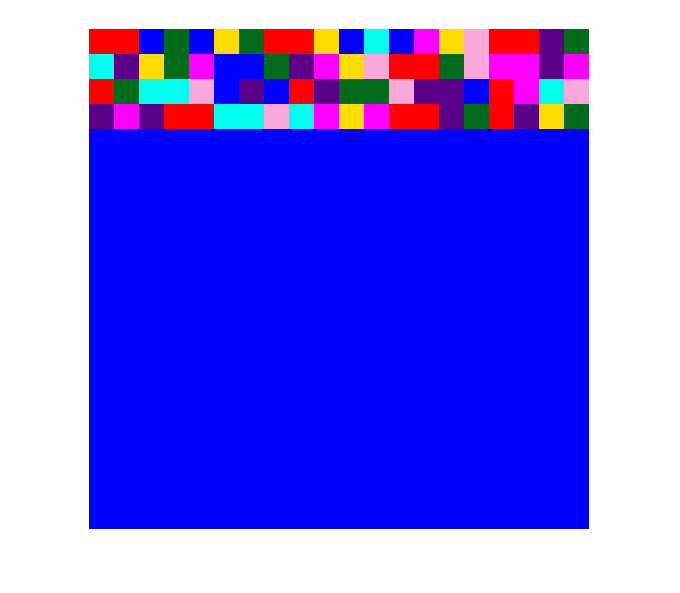

filename = "./transmitterImagesNew/segnet Images/119.jpg"

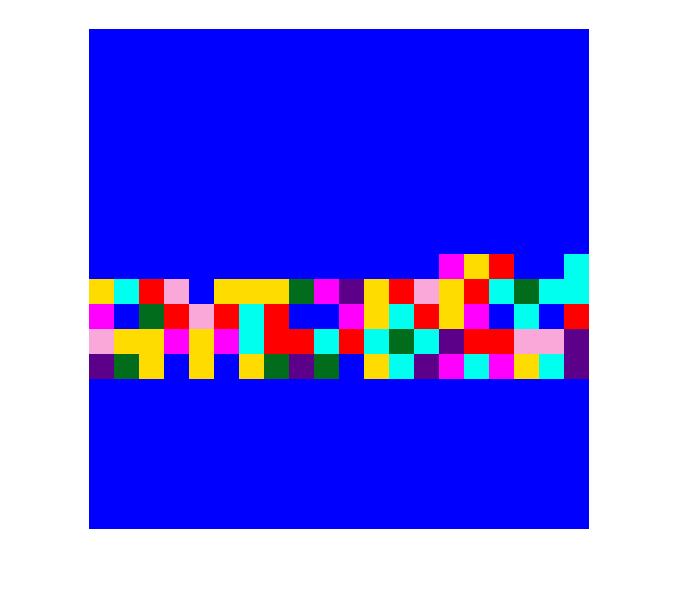

filename = "./transmitterImagesNew/segnet Images/120.jpg"

image=generateImages(symbolStream,20,50);

generateVideo(image);

cd 'C:\Program Files (x86)\VideoLAN\VLC'
!vlc  "C:\Users\eitan\OneDrive\Documents\Fourth Year Files\Research project 2\AILensCleaner\Modulation\myVideo.avi" --fullscreen --no-loop


%decoder code. will remove later
erasuresvector=zeros(1785,1)
[binaryStream,errs] = rsdecoder(encData,erasuresvector)
binaryStream=binaryStream';
for i=1:223
    binaryReceived=string(binaryStream((i-1)*8+1:(i)*8));
    binaryReceived=strjoin(binaryReceived);
    textReceived = char(bin2dec(binaryReceived))
end

filename='received2.txt';
fid = fopen(filename,'w');
fprintf(fid,'%s',textReceived);
fclose(fid);

function y=generateVideo(image)
    numImages=size(image);
    numImages=numImages(4);
    images=cell(numImages+5,1);
    blank=zeros(200,200,3,'uint8');
    images{1}=blank;
    images{2}=blank;
    images{3}=blank;
    for i=4:numImages+3
        images{i}=image(:,:,:,i-3);
    end
    images{numImages+4}=blank;
    images{numImages+5}=blank;
     writerObj = VideoWriter('myVideo.avi');
     writerObj.FrameRate = 1;
     writerObj.Quality=100;
     % set the seconds per image
     framerate = 3;
     % open the video writer
     open(writerObj);
     % write the frames to the video
     for u=1:length(images)
         % convert the image to a frame
         frame = im2frame(images{u});
         
         for v=1:framerate
             
             
             writeVideo(writerObj, frame);
         end
     end
     % close the writer object
     close(writerObj);
end

function [image] =generateImages(stream,size,pixelsize) % generates images from bitstream
symbolsPerFrame=size*size;
numFrames=length(stream)/(symbolsPerFrame)

if (mod(numFrames,1)~=0)%need to generate padding
    
    numCompleteFrames=floor(numFrames);
    numAdditionalSymbols=((size*size)-(length(stream)-symbolsPerFrame*numCompleteFrames))    
    
    stream(end+1:end+numAdditionalSymbols)=0;
    numFrames=numCompleteFrames+1
end

image=zeros(pixelsize*size,pixelsize*size,3,numFrames); %initialize
for j=1:numFrames
    for i=(j-1)*size*size+1:(j)*size*size

        row = floor((i-1)/size)+1;
        col=(i)-(row-1)*size;
        row=mod(row,size);
        if (row==0)
            row=size;
        end

        symbol = stream(i);

        switch symbol
            case(0)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=1;
        
            case(1)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=1;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=1;
               
            case(2)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=1;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=238/255;

            case(3)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=1;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=0;

            case(4)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=93/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=137/255;

            case(5)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=1;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=220/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=0;

            case(6)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=0;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=108/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=28/255;

            case(7)
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),1)=250/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),2)=168/255;
                imageTemp(((row-1)*pixelsize+1):((row-1)*pixelsize+pixelsize),((col-1)*pixelsize+1):((col-1)*pixelsize+pixelsize),3)=218/255;

        end
    end
    k=j+118;
   % image(:,:,:,j)=imageTemp;
    figure, imshow(imageTemp);
      
    filename='./transmitterImagesNew/segnet Images/'+string(k)+'.jpg'
 
    imwrite(imageTemp,filename)
    
end
end